# Exploring table data from an online source with gramm

In this example script, we will pull table data from an open dataset hosted on S3 and will use gramm along with MATLAB's table handling functions to explore the dataset. The dataset we are using is the [Sea Around Us Global Fisheries Catch Data](https://aws.amazon.com/marketplace/pp/prodview-qvau3bavce5q6?sr=0-2&ref_=beagle&applicationId=AWSMPContessa) from the North East Atlantic Fisheries Commission. More details about this dataset can be found on [GitHub](https://github.com/UBC-CIC/Sea-Around-Us/).

% Download data from S3
data = webread('https://fisheries-catch-data.s3.amazonaws.com/global-catch-data/csv/rfmo_12.csv');

%Convert all cellstrings to string
for k=1:length(data.Properties.VariableNames)
    if data.Properties.VariableTypes(k)=="cell"
        data.(data.Properties.VariableNames{k}) = string(data.(data.Properties.VariableNames{k}) );
    end
end

data

data = 1084102×15 table
    rfmo_id    rfmo_name    layer_name    year           scientific_name                common_name               functional_group                commercial_group        fishing_entity    sector_type     catch_status    reporting_status       gear_name       catch_sum    real_value
    _______    _________    __________    ____    ______________________________    ___________________    _______________________________    ________________________    ______________    ____________    ____________    ________________

## Exploring, summarizing and sorting fishing entities

The table stores catch data separated by year, various ways of categorizing fish, fishing entities (countries), and various modalities of fishing. We will start by looking at which countries are most represented in the dataset. First we need to sum all data for each country. For this we will use MATLAB's `groupsummary()`

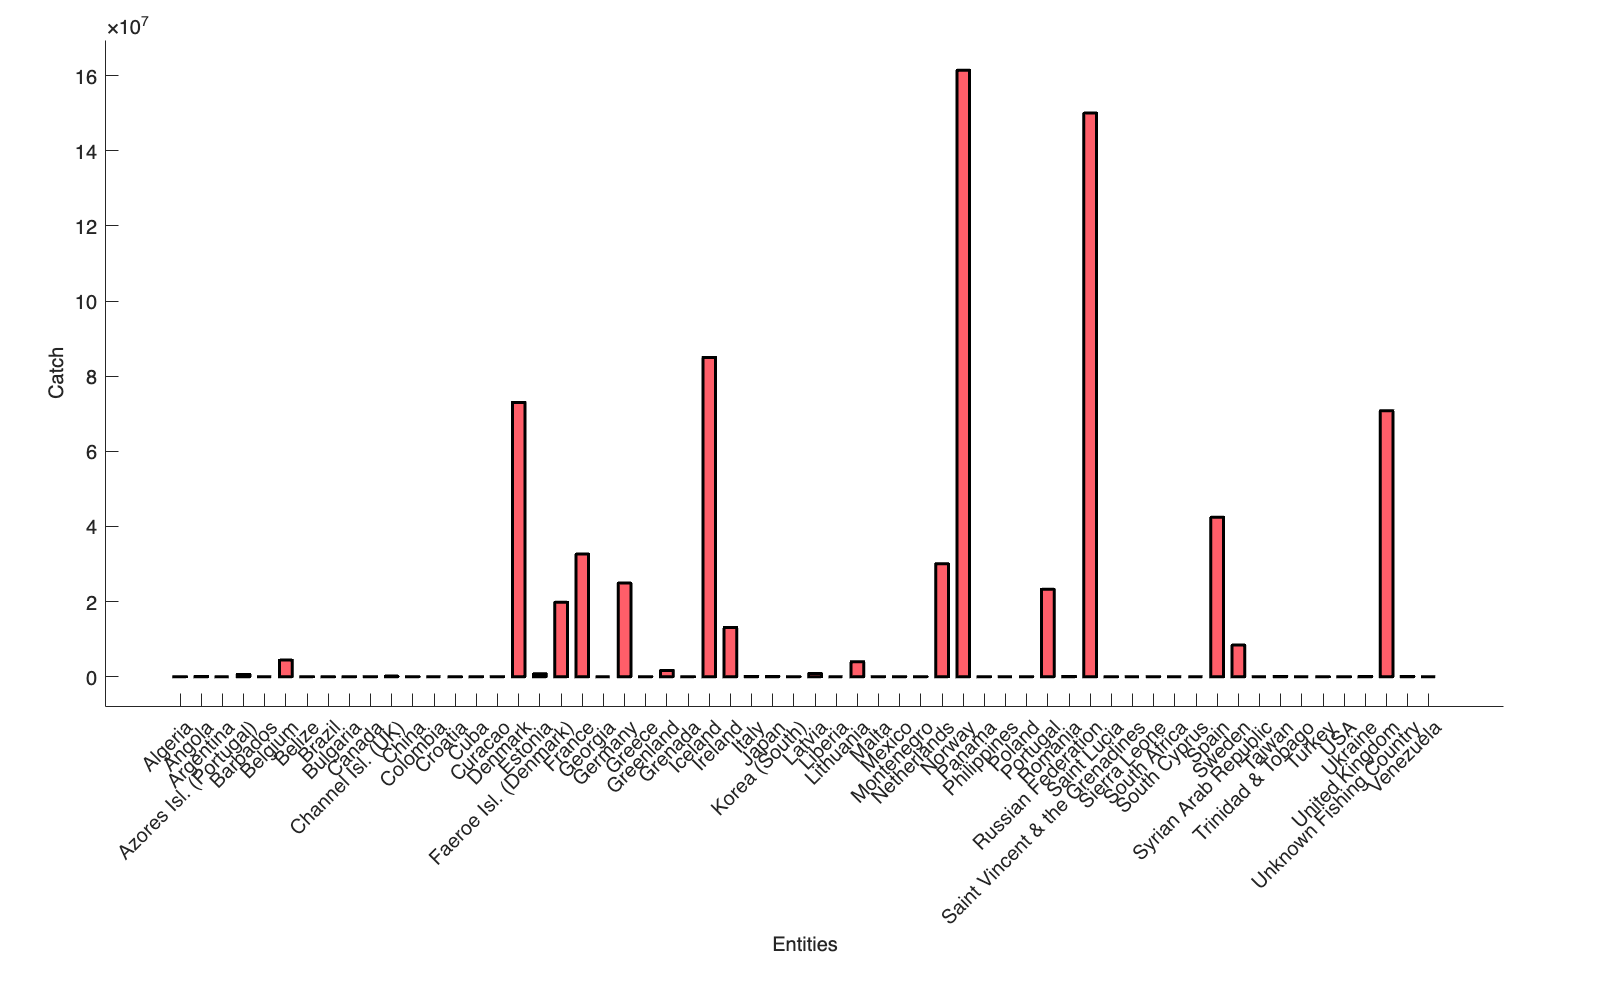

%Create summarized data
summ_entities = groupsummary(data,{'fishing_entity'}, ...
    "sum",{'catch_sum' 'real_value'});

figure('Position',[0 0 800 500])
g=gramm('x',summ_entities.fishing_entity,'y',summ_entities.sum_catch_sum);
g.geom_bar();
g.set_names('y','Catch','x','Entities');
g.draw();

By default, gramm orders categories by alphabetical order. The method set_order_options() provides several options to sort categories either as they appear through the dataset or in a custom order.

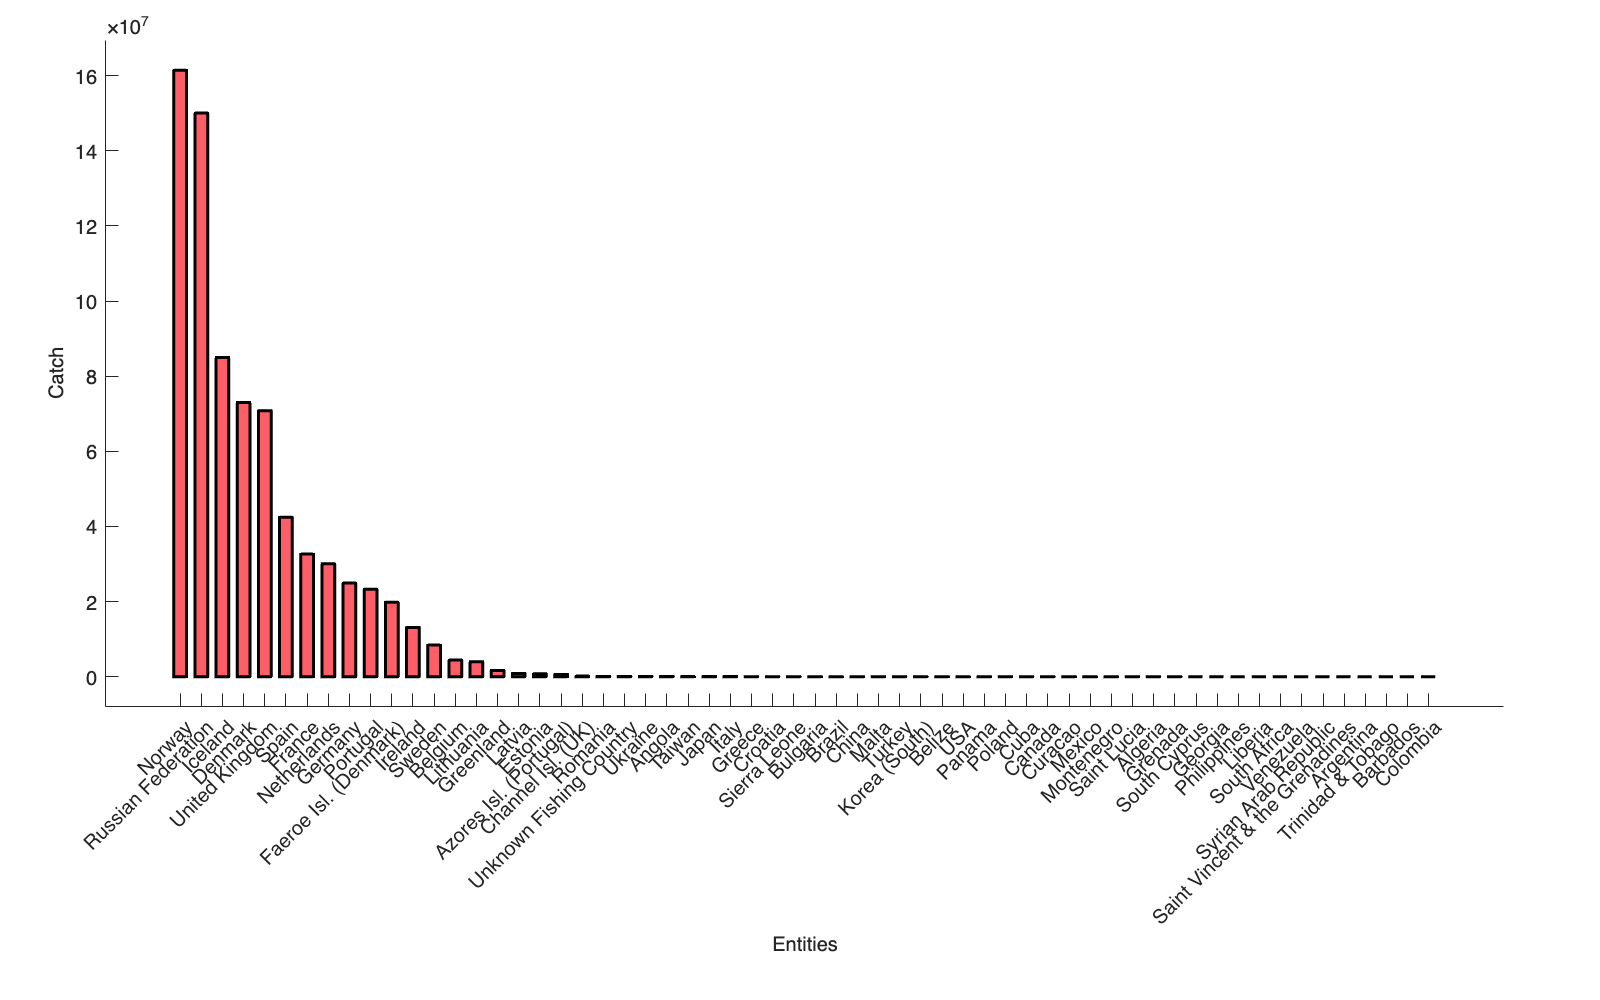

%Reorder the summarized dataset
summ_entities = sortrows(summ_entities,"sum_catch_sum","descend");

figure('Position',[0 0 800 500])
g=gramm('x',summ_entities.fishing_entity,'y',summ_entities.sum_catch_sum);
g.geom_bar();
g.set_order_options('x',0); %Set ordering according to dateset order
g.set_names('y','Catch','x','Entities');
g.draw();

We see that many countries present in the dataset participate little to the overall data, which complicates the figure output, here we will create a new table column that groups all less participating countries in an `"Others" `category.

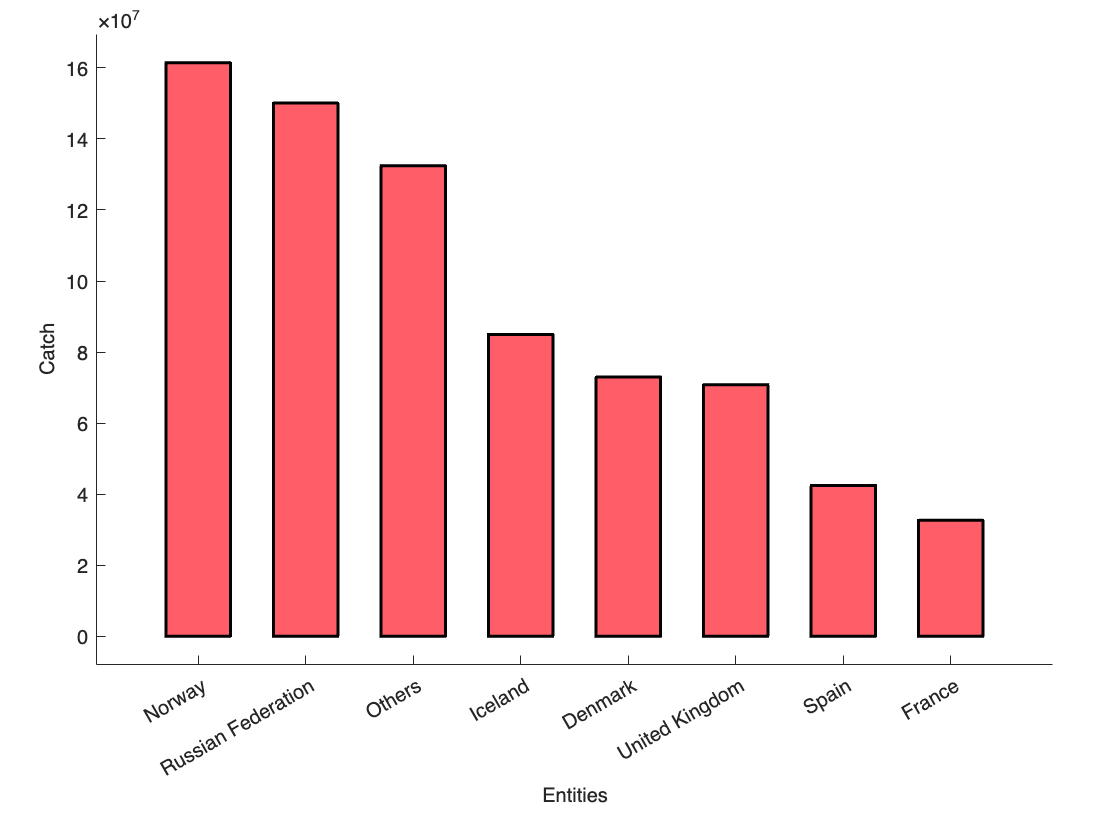

%Create shortened entity list
n_entities = 8;
data.fishing_entity_simplified = data.fishing_entity;
data.fishing_entity_simplified(matches(data.fishing_entity_simplified,summ_entities.fishing_entity(n_entities:end)))="Others";

%Redo the summary
summ_entities = groupsummary(data,{'fishing_entity_simplified'}, ...
    "sum",{'catch_sum' 'real_value'});
summ_entities = sortrows(summ_entities,"sum_catch_sum","descend");

figure
g=gramm('x',summ_entities.fishing_entity_simplified,'y',summ_entities.sum_catch_sum);
g.geom_bar();
g.set_order_options('x',summ_entities.fishing_entity_simplified);
g.set_names('y','Catch','x','Entities');
g.draw();

Now we want to see which group of fish species was most caught by each country. For this we will use a stacked bar plot, and will have both countries and fish groups sorted by overall importance. This necessitates the use of a custom order.

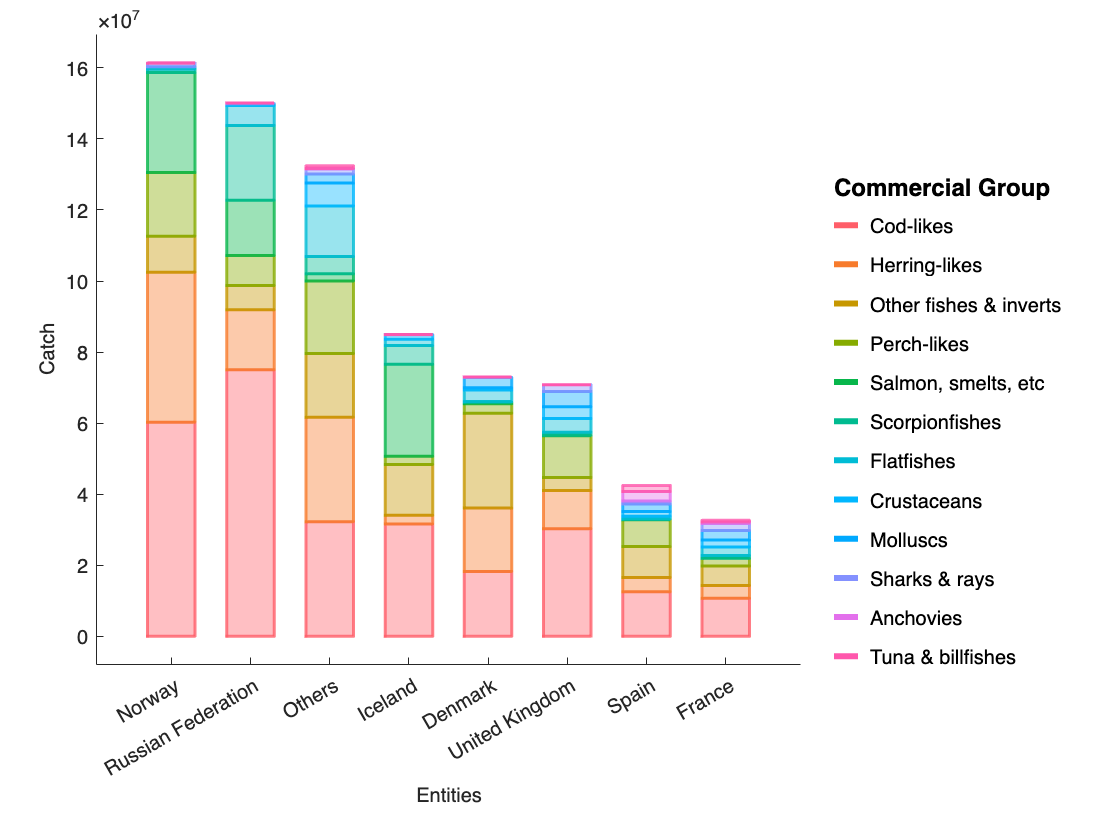

%Create order for fish groups
summ_group = groupsummary(data,{'commercial_group'}, ...
    "sum",{'catch_sum' 'real_value'});
summ_group = sortrows(summ_group,"sum_catch_sum","descend");

%Create summarized dataset over both entities and fish groups
summ_entities_group = groupsummary(data,{ 'commercial_group' 'fishing_entity_simplified'}, ...
    "sum",{'catch_sum' 'real_value'});

figure
g=gramm('x',summ_entities_group.fishing_entity_simplified', ...
    'y',summ_entities_group.sum_catch_sum', ...
    'color',summ_entities_group.commercial_group');
g.geom_bar("stacked",true,'fill','transparent');
g.set_order_options('x',summ_entities.fishing_entity_simplified, ...
    'color',summ_group.commercial_group); %Set custom ordering for both x and color
g.set_names('y','Catch','x','Entities','color','Commercial Group');
g.draw();

## Exploring catch data over time 

Now we want to study the data more in depth and follow the caught fishes over time. For this we will use the broad fish categorization `commercial_group` and will separate by country. To follow countries as well as total amount fished, we will use stacked lines.

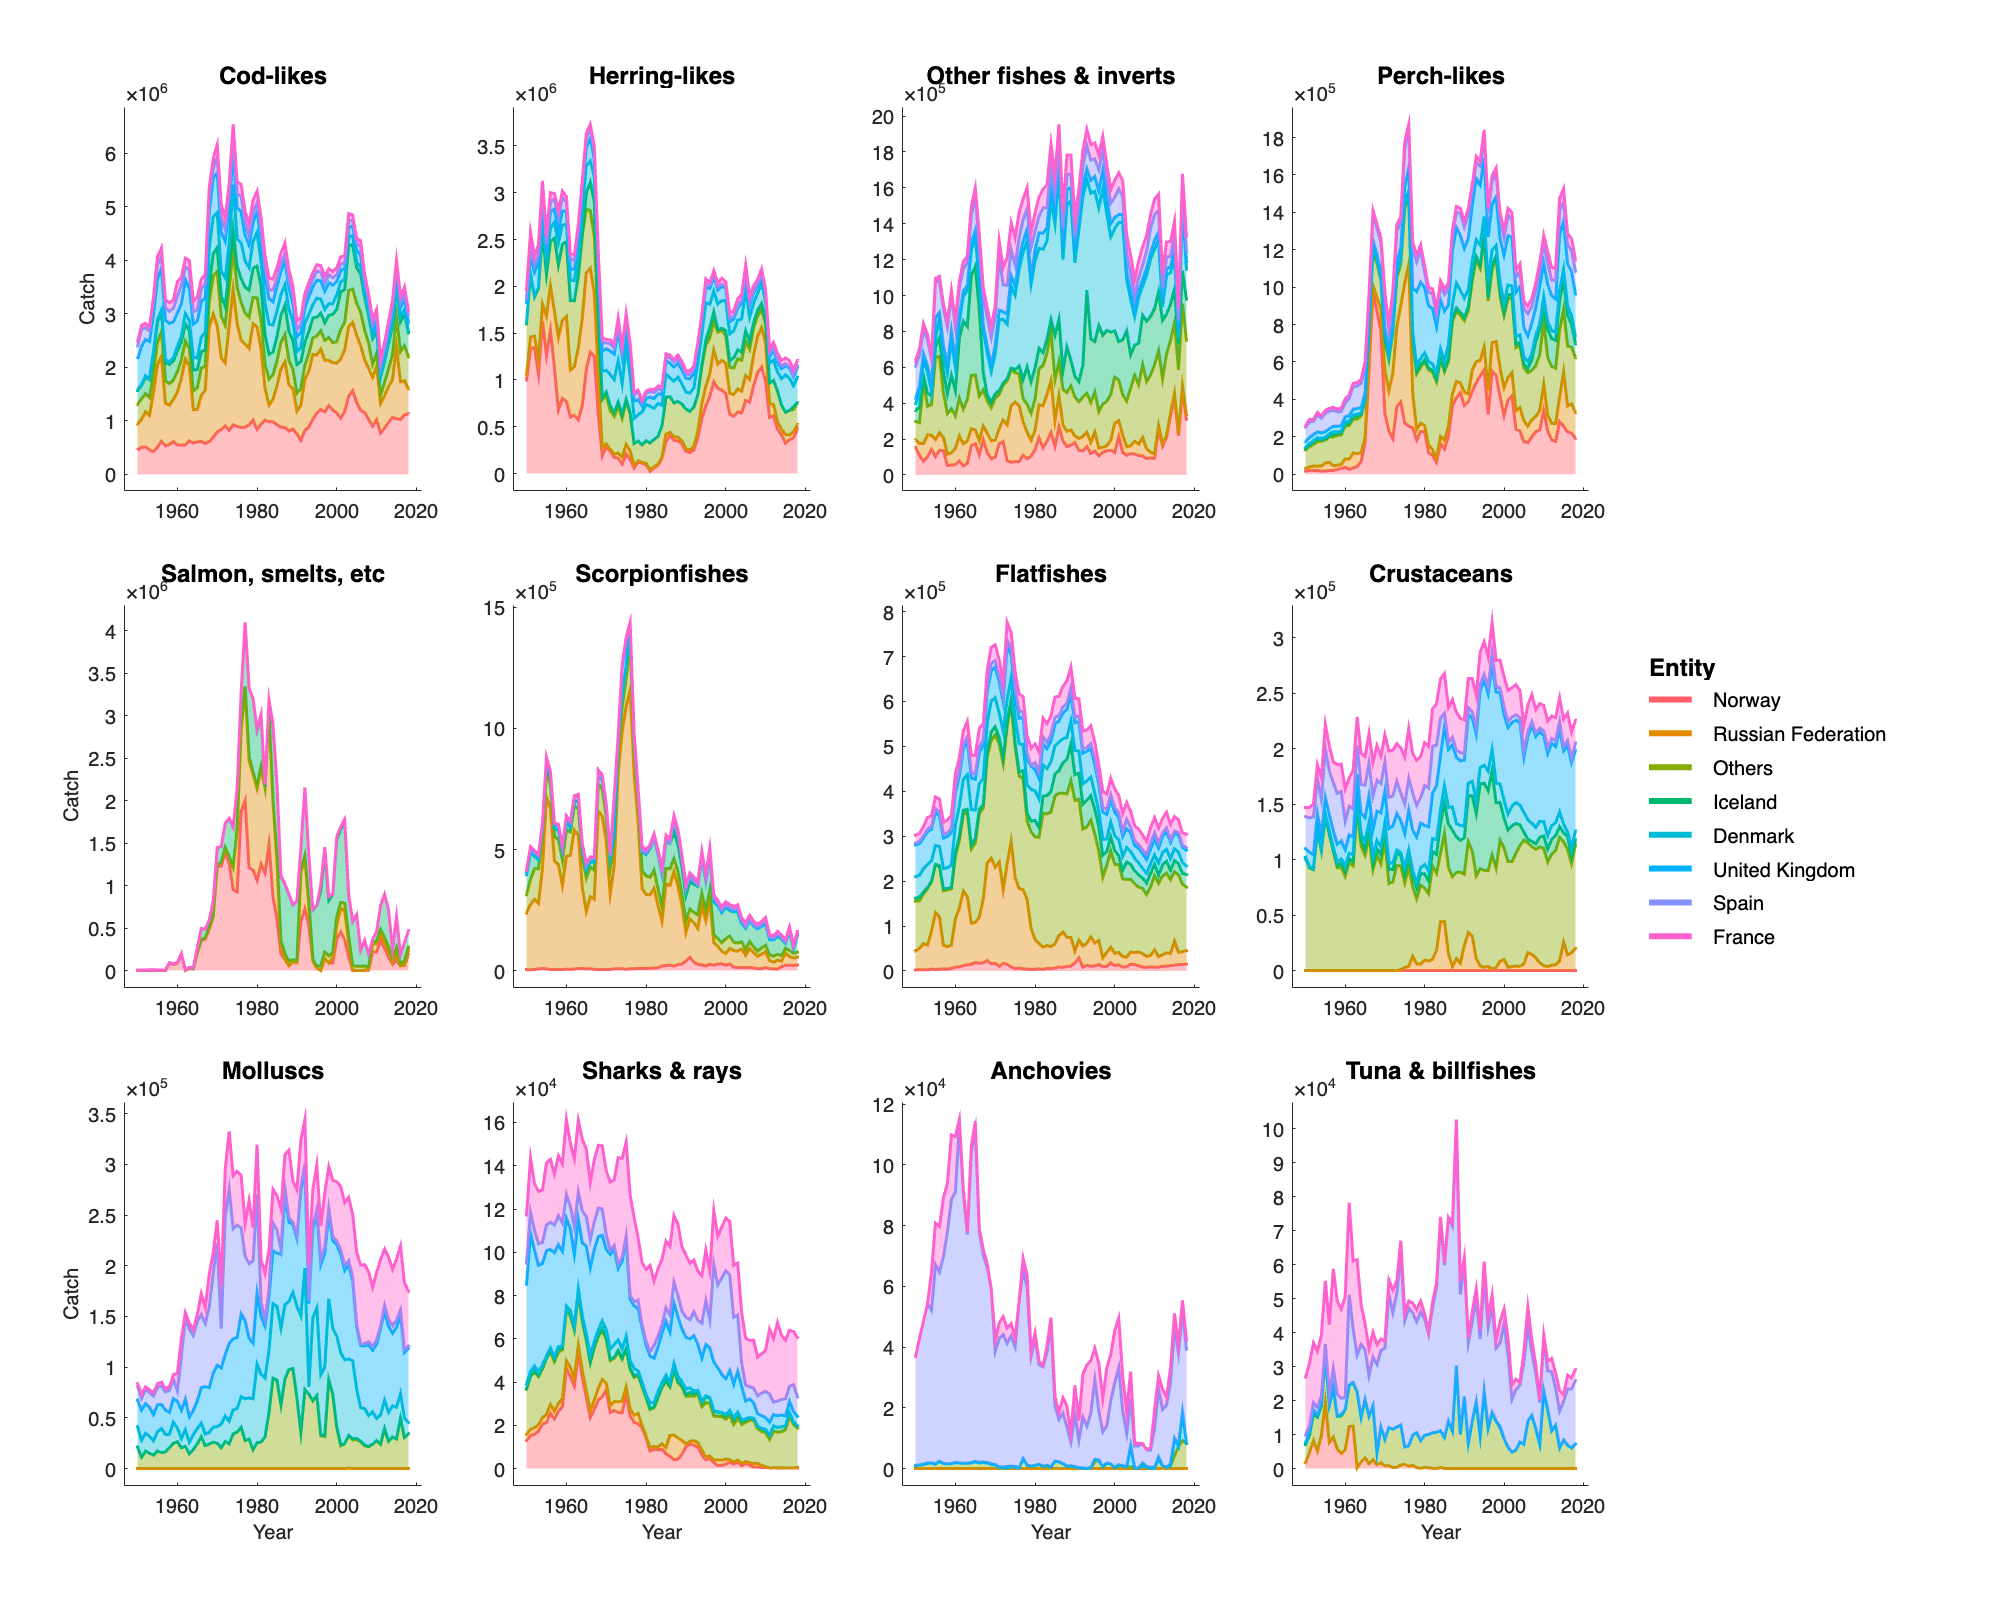

%Create dataset summarized by year, entity and group
summ_year_entities_group = groupsummary(data,{'year' 'fishing_entity_simplified' 'commercial_group'}, ...
    "sum",{'catch_sum' 'real_value'});


figure('Position',[0 0 1000 800])
g=gramm('x',summ_year_entities_group.year, ...
    'y',summ_year_entities_group.sum_catch_sum, ...
    'color',summ_year_entities_group.fishing_entity_simplified);
g.facet_wrap(summ_year_entities_group.commercial_group,"scale","independent"); %Allow each subplot to have its own y scale
g.geom_line("stacked",true);
g.set_order_options('color',summ_entities.fishing_entity_simplified,'column',summ_group.commercial_group); %Custom order
g.set_names('x','Year','y','Catch','column','','color','Entity');
g.draw();

The plot above shows a rapid decreas of catches in the group "Herring-Likes" in the late 1960s. Let us do a plot for the main species within this group, the Atlantic herring. This vizualisation clearly shows the collapse of the herring population in the late 1960s and its slow recovery after catch restrictions were introduced.

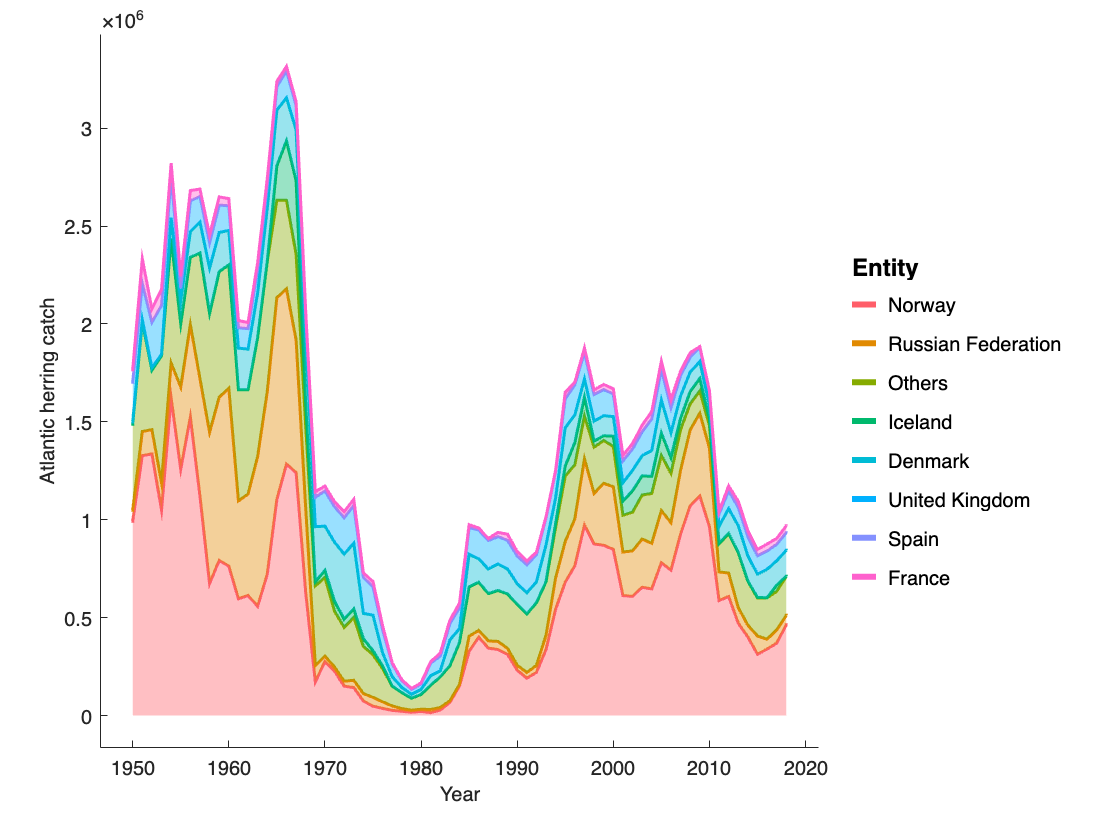

summ_year_entities_herring = groupsummary(data(data.common_name=="Atlantic herring",:),{'year' 'fishing_entity_simplified'}, ...
    "sum",{'catch_sum' 'real_value'});

figure
g=gramm('x',summ_year_entities_herring.year, ...
    'y',summ_year_entities_herring.sum_catch_sum, ...
    'color',summ_year_entities_herring.fishing_entity_simplified);
g.geom_line("stacked",true);
g.set_order_options('color',summ_entities.fishing_entity_simplified); %Custom order
g.set_names('x','Year','y','Atlantic herring catch','column','','color','Entity');
g.draw();

The previous visualization shows that the total catch for each group of fish can vary considerably from year to year. In order to better appreciate the relative contributions of different countries, we can plot the percentage of catches by each country each year. For this we need to compute a ratio based on data summarized at different levels. This will be done by joining summary tables.

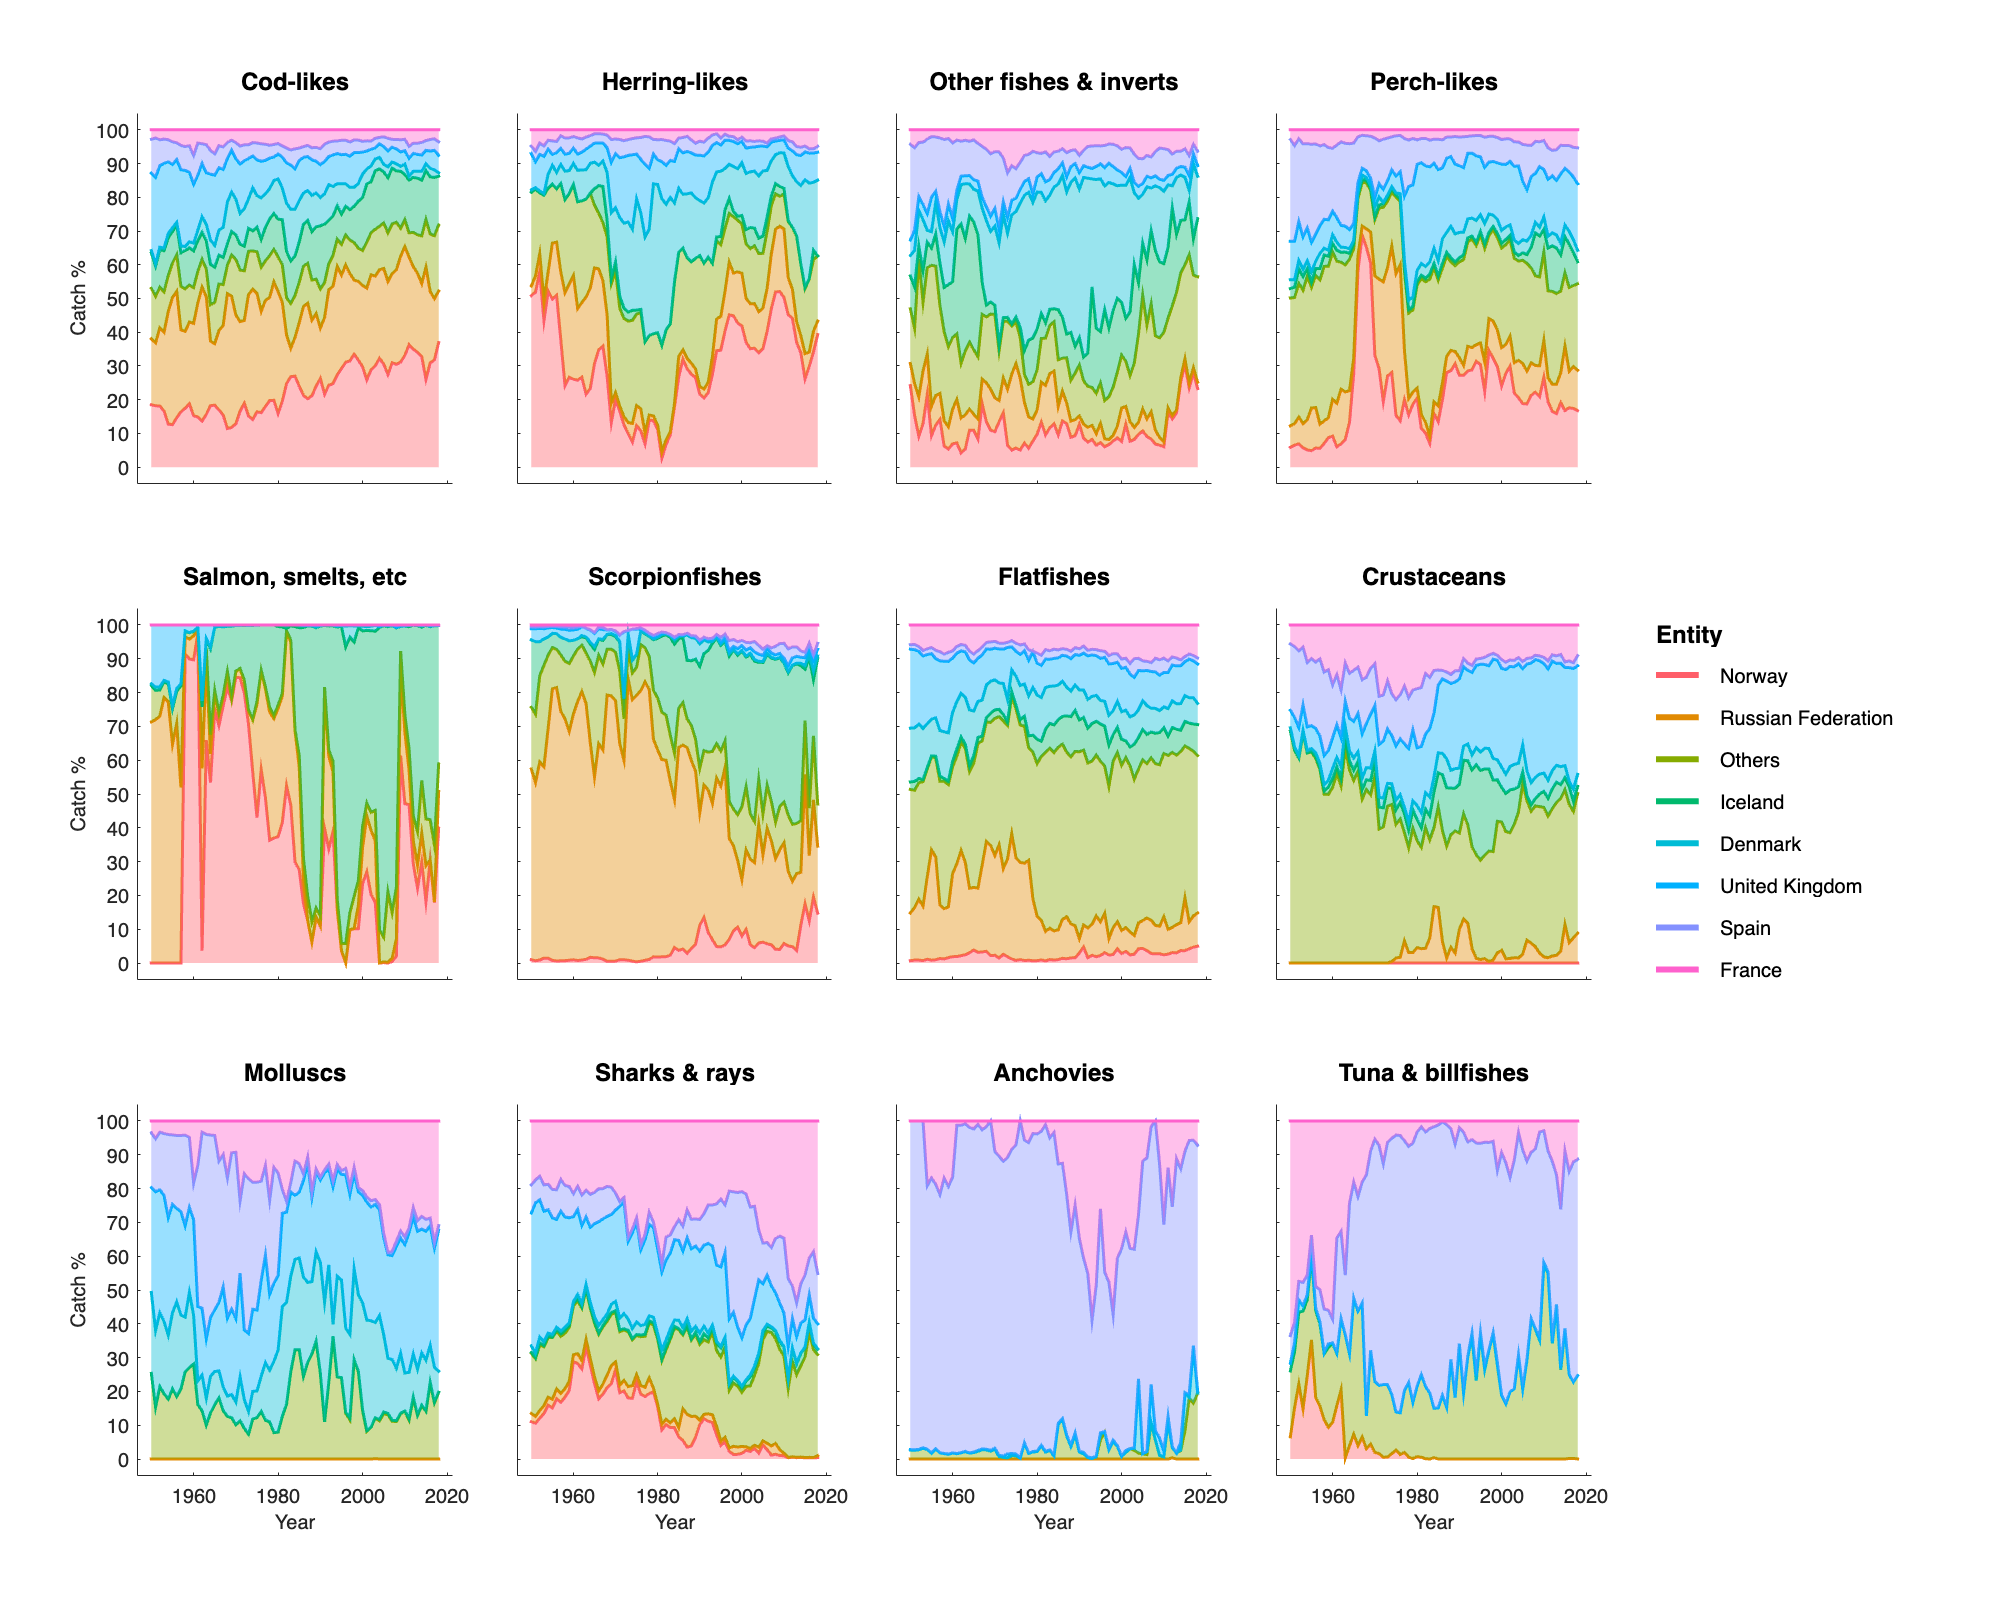

%Create summarized data by year and group
summ_year_group = groupsummary(data,{'year' 'commercial_group'}, ...
    "sum",{'catch_sum'});
%Change variable name to avoid confusion after join
summ_year_group.Properties.VariableNames{'sum_catch_sum'} = 'sum_catch_year_group';

%Bring data summarized by year and group in the year/entities/group table
summ_year_entities_group = join(summ_year_entities_group,summ_year_group,'Keys',{'year' 'commercial_group'});

%Calculate percentage
summ_year_entities_group.sum_catch_proportion = 100*summ_year_entities_group.sum_catch_sum./summ_year_entities_group.sum_catch_year_group;

figure('Position',[0 0 1000 800])
g=gramm('x',summ_year_entities_group.year, ...
    'y',summ_year_entities_group.sum_catch_proportion, ...
    'color',summ_year_entities_group.fishing_entity_simplified);
g.facet_wrap(summ_year_entities_group.commercial_group);
g.geom_line('stacked',true);
g.set_order_options('color',summ_entities.fishing_entity_simplified,'column',summ_group.commercial_group);
g.set_names('x','Year','y','Catch %','column','','color','Entity');
g.draw();
%Export
g.export('file_name','stacked_export','file_type','png');